# Least-Squares Batch Identification Algorithm - Example

## Identifying an ARX(2, 2) Stochastic Process

La tecnica di minimizzazione vista nella L12 va bene solo se devo ottimizzare per un parametro solo, se ne ho di piu` devo usare il least squares.

Consider the stationary stochastic process $\mathcal{S}$ 


$$\mathcal{S}: \qquad y(t) = \displaystyle+\frac{6}{5}\ y(t-1) - \frac{8}{25}\,y(t-2) + u(t-1) +\frac{1}{2}\,u(t-2) + \xi(t) $$



$$\xi(\cdot ) \sim \mathrm{WN}\left(0, 1\right)\;,\quad u(\cdot) \sim \mathrm{WN}\left(0,\,4\right) \qquad e(\cdot), u(\cdot) \, \, \textrm{uncorrelated}$$


and collect $N_1 = 1500$ samples of both $y(t)$ and $u(t)$


$$Y = \big\{ y(1),\, y(2),\, \ldots y(N_1) \big\} \qquad U = \big\{ u(1),\, u(2),\, \ldots u(N_1) \big\}$$


Consider the model $\mathcal{M}$ (caso del teorema 2)


$$\mathcal{M}\left(\vartheta\right) : y(t) = a_1 \,y(t-1) +a_2\,y(t-2) + b_1\,u(t-1) + b_2\, u(t-2) + \eta(t) \qquad \mathrm{var}\left[\eta\left(\cdot\right)\right]= \lambda^2$$


and let us identify the model. Let us resort to the **Least-Squares** technique. Then


$$\vartheta =
\left [
\begin{array}{c}
a_1 \\
a_2 \\
b_1 \\
b_2
\end{array}
\right ]
\quad
\varphi (t)=
\left [
\begin{array}{c}
y(t-1) \\
y(t-2) \\
u(t-1) \\
u(t-2) \\
\end{array}
\right ]$$


and hence


$$\begin{array}{l}
\mathcal{M} (\vartheta) \, \colon \quad
y(t)=
\varphi(t)^{\top}  \, \vartheta+ \eta(t) \\
\widehat {\mathcal{M}} (\vartheta) \, \colon \quad
\hat{y} \left(t \vert t-1 \right)=
\varphi(t)^{\top}  \, \vartheta
\end{array}$$


The **predictor** has a **linear** **structure** with respect to the **vector **$\vartheta$** of unknown parameters**.

The prediction error $\epsilon(t)$ is given by


$$\varepsilon (t)=
y(t)-\hat{y} \left(t \vert t-1 \right)=
y(t)-
\varphi(t)^{\top}  \, \vartheta$$


Consider the quadratic cost function


$$J(\vartheta)= \frac{1}{N_1}
\sum_{t=1}^{N_1} \,
[\varepsilon(t)]^2 =
 \frac{1}{N_1} \sum_{t=1}^{N_1} \,
\left [
y(t)-\varphi(t)^{\top} \vartheta
\right ]^2$$


and the minimizing vector 


$$\vartheta^{\circ} =
{\rm arg} \, \min_{\vartheta} \,
J(\vartheta)$$


If $\,  \sum_{t=1}^N \,\varphi(t)\, \varphi(t)^{\top}  \,$ is  **non-singular**, one gets:


$$\hat \vartheta_{N_1} =
\left [ \,\sum_{t=1}^{N_1} \,\varphi(t)
\, \varphi(t)^{\top} \, \right ]^{-1}
\, 
\sum_{t=1}^{N_1} \,
\varphi(t) \, y(t) $$


and the estimate uncertainty is


$$\mathrm{var}\left[\hat{\vartheta}_{N_1}\right] = \hat{\lambda}^2_{N_1}\, \left [ \,\sum_{t=1}^{N_1} \,\varphi(t)
\, \varphi(t)^{\top} \, \right ]^{-1}$$


where $\hat{\lambda}^2_{N_1}$is an empirical estimate of $\lambda^2$


$$\hat{\lambda}^2_{N_1} =  \frac{1}{N_1} \sum_{t=1}^{N_1} \,
\left [
y(t)-\varphi(t)^{\top} \hat{\vartheta}_{N_1}
\right ]^2$$


The condition 


$${\rm det} \,\left [ \,\sum_{t=1}^N \,\varphi(t)
\, \varphi(t)^{\top} \, \right ] \not= 0$$


is called **Identifiability Condition**.

### ARX Process Simulation

#### Generation of the Data

clear
close all
clc

N1 = 50; % the number of sample data to simulate and collect, vedere come cambiano i risultati se cambio questo

var_xi = 1;  % the white noise variance
mean_xi = 0; % the white noise mean value

var_u = 4;  % the input variable variance 
mean_u = 0; % the input variable mean value

Az1 = [1,  -6/5,  +8/25]; 
% the coefficients of the polynomial A(z) <-> 1 - a_1 * z^(-1) - a_2 * z^(-2)
%                                           z^2 - a_1 * z^1    - a_2 * z^ 0

Bz1 = [0,  1,  1/2]; 
% the coefficients of the polynomial B(z) <-> b_1 * z^(-1) + b_2 * z^(-2)
%                                             b_1 * z^1    + b_2 * z^ 0
Ts = 1; % sampling time 
Gz1 = tf(Bz1, Az1, Ts, 'Variable', 'z^-1')

Gz1 =
 
      z^-1 + 0.5 z^-2
  ------------------------
  1 - 1.2 z^-1 + 0.32 z^-2
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Gz = tf(Bz1, Az1, Ts, 'Variable', 'z')

Gz =
 
       z + 0.5
  ------------------
  z^2 - 1.2 z + 0.32
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Let's estimate how long is the initial transient output of the filter $Gz) = \frac{B(z)}{A(z)}$:


p_vector = pole(Gz); % the poles of W(z)
z_vector = zero(Gz); % the zeros of W(z)

slowest_pole = max(abs(p_vector));

zero_threshold = 1e-8; 
% let's assume that the value is practically zero if less than or equal to zero_threshold
Ntransient = 50*(ceil(log10(zero_threshold)/log10(slowest_pole))+10); % a very raw estimation

N_TOT_data = N1 + Ntransient

N_TOT_data = 4700

rng('shuffle'); 
%     seeds the random number generator based on the current
%     time so that RAND, RANDI, and RANDN produce a different sequence of
%     numbers after each time you call rng.
WN_samples = mean_xi + sqrt(var_xi)*randn(1, N_TOT_data); % the white noise sequence

rng('shuffle');
U_samples = mean_u + sqrt(var_u)*randn(1, N_TOT_data);    % the input u sequence


**Remember**: the stochastic process $\mathcal{S}$ is an $ARX$ process


$$\mathcal{S}: \qquad y(t) = \displaystyle+\frac{6}{5}\ y(t-1) - \frac{8}{25}\,y(t-2) + u(t-1) +\frac{1}{2}\,u(t-2) + \xi(t) \qquad (+)$$


Let us rewrite the model $\mathcal{S}$, pointing in evidence the filters $G(z)$ and $W(z)$:


$$\left[ 1 - \displaystyle \frac{6}{5}\,z^{-1}+\frac{8}{25}\,z^{-2} \right]\, y(t) = 
\left[ z^{-1}+\displaystyle \frac{1}{2}\,z^{-2} \right] \, u(t) + \xi(t)$$
 


$$A(z) \, y(t) = B(z) \, u(t) + \xi(t) \qquad A(z) = \left[ 1 - \displaystyle \frac{6}{5}\,z^{-1}+\frac{8}{25}\,z^{-2} \right] \quad B(z) = \left[ z^{-1}+\displaystyle \frac{1}{2}\,z^{-2} \right]$$



$$y(t) = \displaystyle \frac{B(z)}{A(z)}\,u(t) + \frac{1}{A(z)}\, \xi(t) \qquad  G(z) = \frac{B(z)}{A(z)} \quad    W(z) = \frac{1}{A(z)}$$


Finally


$$y(t) = G(z) \,u(t) + W(z) \, \xi(t) \qquad (\star)$$


Now we may generate a set of data of the process $\mathcal{S}$, using the Eq. $(\star)$ or the explicit difference equation in Eq. $(+)$.

% let us generate samples using Eq. (*)
% Remember: describe the numerator and denominator of both the transfer 
% functions G(z) and W(z)using the notation with ascending powers of z^-1

V_ARX_tot = filter(Bz1, Az1, U_samples) +...
               filter(1, Az1, WN_samples); % G(z)*u(t) + W(z)*xi(t)

V_ARX = V_ARX_tot(Ntransient+1:end); %#ok<*NASGU> 
% let's retrieve the N1 samples when the initial transient part is over


Let us implement Eq. $(+)$ to generate the samples.

v_y = zeros(1, N_TOT_data); % the array recipient for the r.v. y(t) in Eq.(+)

% --- solving Eq. (+) in a "for" loop ---
for k=1:N_TOT_data

    % ---- checking if the values 
    %      at the time instant (t-2) are available ----
    if ((k-2)>0)               % if available, then use them
        vy_k2 = v_y(k-2);
        u_k2 = U_samples(k-2);
    else                       % if not available then set them to zero
        vy_k2 = 0;
        u_k2 = 0;
    end % if ((k-2)>0)

    % ---- checking if the values 
    %      at the time instant (t-1) are available ----
    if ((k-1)>0)               % if available, then use them
        vy_k1 = v_y(k-1);
        u_k1 = U_samples(k-1);
    else                       % if not available then set them to zero
        vy_k1 = 0;
        u_k1 = 0;
    end % if ((k-1)>0)

    % ---- evaluate y(t) according to Eq. (+) ----
    v_y(k) = -Az1(2)*vy_k1 -Az1(3)*vy_k2 +...
               +Bz1(1)*U_samples(k) +Bz1(2)*u_k1+Bz1(3)*u_k2 +...
                   WN_samples(k);
end


Let us compare the resulting sequences:

compare_S_sequences = abs(v_y-V_ARX_tot);
V_ARX_tot(1:6)-v_y(1:6)

ans = 1.0e-15 *

         0         0    0.2220    0.6661    0.6661    0.8882


fprintf(1, "*** Max abs value of the difference between the two sequences: %e ***\n", ...
          max(compare_S_sequences));

*** Max abs value of the difference between the two sequences: 1.421085e-14 ***


Both approaches lead to the same sequence.

#### The Dataset

V_ARX = V_ARX_tot(Ntransient+1:end); 
% the N1 samples, collected when the initial transient
% (due to the initial simulation conditions) has practically disappeared 

### Plot the Process Data

Let us define a set of colors

% ---- possible colors ----
FrenchBlue   = [0 0.4470 0.7410];      % French Blue
FlameRed     = [0.8500 0.3250 0.0980]; % Flame Red
Xanthous     = [0.9290 0.6940 0.1250]; % Xanthous
VividViolet  = [0.4940 0.1840 0.5560]; % Vivid Violet
AppleGreen   = [0.4660 0.6740 0.1880]; % Apple Green
BlizzardBlue = [0.3010 0.7450 0.9330]; % Blizzard Blue
VividBurgundy = [0.6350 0.0780 0.1840]; % Vivid Burgundy
% ---- possible colors ----


and plot the collected data:

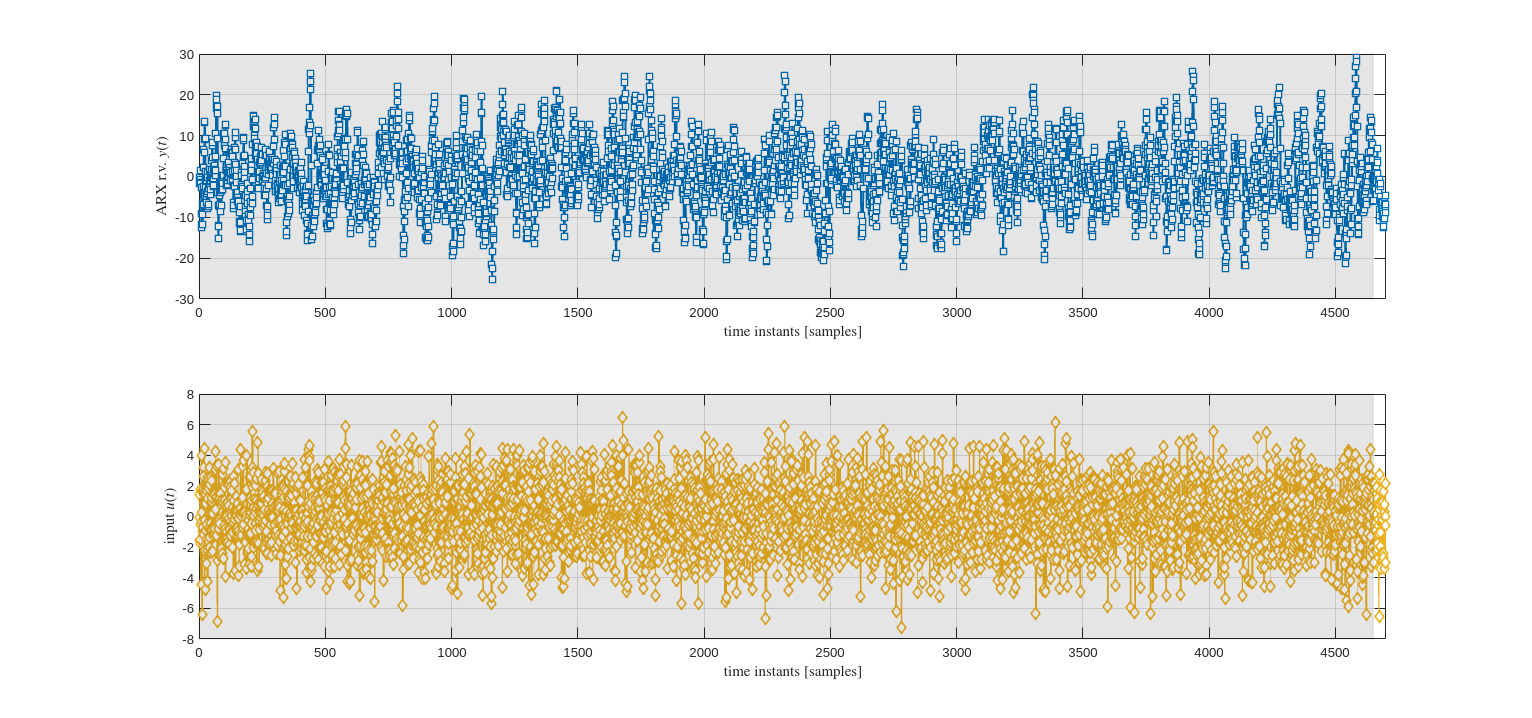

figure('Units','normalized', 'Position', [0.1, 0.1, 0.9, 0.75]);
hp1 = subplot(2, 1, 1);
plot(V_ARX_tot, 'Color', FrenchBlue , 'LineWidth', 1.5, 'LineStyle','-', 'Marker','square', ...
      'MarkerSize', 6, 'MarkerEdgeColor','auto', 'MarkerFaceColor','auto');
grid on; hold on;
xlabel('time instants [samples]', 'Interpreter','latex');
ylabel('ARX r.v. $y(t)$', 'Interpreter','latex');
xlim([0, numel(V_ARX_tot)]); % adjusting the x-axis limits
% the gray part corresponds to the transient part of the whitening filter response
YL = ylim;
fill([1 ,Ntransient(end), Ntransient(end), 1], [YL(1), YL(1), YL(2), YL(2)],...
       'k', 'FaceAlpha', 0.10, 'EdgeColor', 'k', 'EdgeAlpha', 0.10); 

hp2 = subplot(2, 1, 2);
plot(U_samples, 'Color', Xanthous , 'LineWidth', 1.5, 'LineStyle','-', 'Marker','diamond', ...
      'MarkerSize', 6, 'MarkerEdgeColor','auto', 'MarkerFaceColor','auto');
grid on; hold on;
xlabel('time instants [samples]', 'Interpreter','latex');
ylabel('input $u(t)$', 'Interpreter','latex');
xlim([0, numel(V_ARX_tot)]); % adjusting the x-axis limits
% the gray part corresponds to the transient part of the whitening filter response
YL = ylim;
fill([1 ,Ntransient(end), Ntransient(end), 1], [YL(1), YL(1), YL(2), YL(2)],...
       'k', 'FaceAlpha', 0.10, 'EdgeColor', 'k', 'EdgeAlpha', 0.10); 
linkaxes([hp1, hp2], 'x');

### Persistency of Excitation and the Identifiability Condition

The regressor $\varphi(t)$ is given by 


$$\varphi(t) = \left[ \begin{array}{c}
y(t-1) \\
y(t-2) \\
u(t-1)\\
u(t-2) 
\end{array} \right]
$$


and consequently, the matrices $S$ and $R$ take on the expressions


$$S(N_1) =
\left [
\begin{array}{cccc}
{\displaystyle \sum_{t=3}^{N_1} 
\left[y(t-1)\right]^2} & 
{\displaystyle \sum_{t=3}^{N_1}  
y(t-1) y(t-2)} &
{\displaystyle \sum_{t=3}^{N_1}  
y(t-1) u(t-1)} &
{\displaystyle \sum_{t=3}^{N_1}  
y(t-1) u(t-2)} 
\\
{\displaystyle \sum_{t=3}^{N_1}  
y(t-2) y(t-1)} &
{\displaystyle \sum_{t=3}^{N_1} 
\left[y(t-2)\right]^2} & 
{\displaystyle \sum_{t=3}^{N_1}  
y(t-2) u(t-1)} &
{\displaystyle \sum_{t=3}^{N_1}  
y(t-2) u(t-2)} 
\\
{\displaystyle \sum_{t=3}^{N_1}  
u(t-1) y(t-1)} & 
{\displaystyle \sum_{t=3}^{N_1}  
u(t-1) y(t-2)} & 
{\displaystyle \sum_{t=3}^{N_1}  
\left[u(t-1)\right]^2} &
{\displaystyle \sum_{t=3}^{N_1}  
u(t-1) u(t-2)} 
\\
{\displaystyle \sum_{t=3}^{N_1}  
u(t-2) y(t-1)} &
{\displaystyle \sum_{t=3}^{N_1} 
u(t-2) y(t-2)} & 
{\displaystyle \sum_{t=3}^{N_1}  
u(t-2) u(t-1)} &
{\displaystyle \sum_{t=3}^{N_1}  
 \left[u(t-2)\right]^2} 
\end{array}
\right ] \qquad R\left( N_1\right) = \displaystyle \frac{1}{N_1-2} S\left(N_1\right)$$


Remark: there is a more efficient way to evaluate the matrix  $S$. In fact, given $N_1$ observations, we build the following matrices and vectors


$$\Phi_{N_1} =
\left [
\begin{array}{c}
\varphi(1)^{\top} \\
\vdots \\
\varphi(N_1)^{\top}
\end{array}
\right ] 
\quad
\varphi (t)=
\left [
\begin{array}{c}
y(t-1) \\
y(t-2) \\
u(t-1) \\
u(t-2)
\end{array}
\right ]
\qquad \vartheta =
\left [
\begin{array}{c}
a_1 \\
a_2 \\
b_1 \\
b_2
\end{array}
\right ]
\qquad Y_{N} =
\left [
\begin{array}{c}
y(1) \\
\vdots \\
y(N_1)
\end{array}
\right ]
$$


Now rewrite the LS problem in a compact form as


$$\Phi_{N_1}\cdot \vartheta = Y_{N_1}$$


To obtain the *LS normal equations* in compact form, simply multiply both terms of this expression to the left using the transposed matrix $\Phi_{N_1}^{\top}$:


$$\Phi_{N_1}^{\top} \, \Phi_{N_1}\,\vartheta = \Phi_{N_1}^{\top} \, Y_{N_1}$$


Finally


$$S = \Phi_{N_1}^{\top} \, \Phi_{N_1}$$


Now we may 

- check if $\Phi_{N_1}^{\top} \, \Phi_{N_1}$ is a full rank matrix (i.e. if the identifiability condition is fulfilled);

- check if the sub-matrix $S_{uu}$ is full-rank (i.e. if we have persistency of excitation - a necessary condition for the identifiability condition to hold true)


$$S_{uu}(N_1) =
\left [
\begin{array}{cc}
{\displaystyle \sum_{t=3}^{N_1}  
\left[u(t-1)\right]^2} &
{\displaystyle \sum_{t=3}^{N_1}  
u(t-1) u(t-2)} 
\\
{\displaystyle \sum_{t=3}^{N_1}  
u(t-2) u(t-1)} &
{\displaystyle \sum_{t=3}^{N_1}  
 \left[u(t-2)\right]^2} 
\end{array}
\right ]$$


#### The Identifiability Condition

U = U_samples(Ntransient+1:end);
Y = V_ARX;
matPHI = zeros(N1-1, 4); % preallocation of the PHI regressors matrix

for k=3:N1
    matPHI(k,:) = [Y(k-1), Y(k-2), U(k-1), U(k-2)];
end % for k
matPHI(1:2,:) = []; % we can not evaluate the model for t=1 and t=2
Y_N1 = Y(3:end)';   % we can not evaluate the model for t=1 and t=2

S_N1 = matPHI'*matPHI;
if (rank(S_N1)<4)
    error('Matrix S not invertible! Identifiability condition not fulfilled!')
else
    disp('Matrix S invertible! Identifiability condition fulfilled!')
end    

Matrix S invertible! Identifiability condition fulfilled!


### Identification - the LS Algorithm


$$\hat \vartheta_{N_1} =
\left [ \,\sum_{t=1}^{N_1} \,\varphi(t)
\, \varphi(t)^{\top} \, \right ]^{-1}
\, 
\sum_{t=1}^{N_1} \,
\varphi(t) \, y(t) $$


or in compact form (refer to the previous section of the live script where we recall it)


$$\Phi_{N_1}\cdot \vartheta = Y_{N_1}$$



$$\Phi_{N_1}^{\top} \, \Phi_{N_1}\,\vartheta = \Phi_{N_1}^{\top} \, Y_{N_1}$$


Thus we may solve the LS equation using the MATLAB operator " \ " using the compact formulation $\Phi_{N_1}\cdot \vartheta = Y_{N_1}$

hat_theta_N1 = matPHI \ Y_N1

hat_theta_N1 =     1.1438
   -0.2740
    0.9796
    0.5685


Alternatively, we may solve the LS normal equations $\Phi_{N_1}^{\top} \, \Phi_{N_1}\,\vartheta = \Phi_{N_1}^{\top} \, Y_{N_1}$, exploiting one more time the operator " \ "

hat_theta_N1_ALT = S_N1 \ (matPHI'*Y_N1)

hat_theta_N1_ALT =     1.1438
   -0.2740
    0.9796
    0.5685


As can be seen, both approaches lead to the same solution.

[-Az1(2)
-Az1(3)
Bz1(2)
Bz1(3)
]

ans =     1.2000
   -0.3200
    1.0000
    0.5000


Comparando con i dati reali, l'approssimazione e` buona

### The Estimate Uncertainty

What about the estimate uncertainty? 

According to the theoretical result, described in the class material (refer to L12 - p. 24), for $N$ sufficiently large the variance of the estimator is $\frac{1}{N}\,\mathrm{var}\left[\epsilon\left(\vartheta^{o}\right)\right]\,\big[\bar{R}\left(\vartheta^{o}\right)\big]^{-1}$

Computing the empirical estimate, one gets


$${\rm var} \, [ \hat \vartheta_N ] =
\frac{\hat{\lambda}^2}{N} \, \left [
\frac{1}{N} \, \sum_{t=1}^N \,
\varphi(t) \, \varphi(t)^{\top} \right ]^{-1}
= \hat{\lambda}^2 \, S(N)^{-1}$$


where


$$\hat{\lambda}^2 =  \frac{1}{N} \sum_{t=1}^{N} \,
\left [
y(t)-\varphi(t)^{\top} \hat{\vartheta}_{N}
\right ]^2$$


In this example one gets

% the estimate of the prediction error variance
pred_residuals = Y_N1 - matPHI*hat_theta_N1;
hat_lambda2_N1 = mean((pred_residuals).^2) 

hat_lambda2_N1 = 1.0005

cond(S_N1)

ans = 71.8675

var_theta_N1 = hat_lambda2_N1 .* inv(S_N1)

var_theta_N1 =     0.0072   -0.0068    0.0014   -0.0055
   -0.0068    0.0069   -0.0015    0.0050
    0.0014   -0.0015    0.0070   -0.0001
   -0.0055    0.0050   -0.0001    0.0106


Alternatively

R_N1 = S_N1 ./ N1;
cond(R_N1)

ans = 71.8675

var_theta_N1_ALT = (hat_lambda2_N1/N1) .* inv(R_N1)

var_theta_N1_ALT =     0.0072   -0.0068    0.0014   -0.0055
   -0.0068    0.0069   -0.0015    0.0050
    0.0014   -0.0015    0.0070   -0.0001
   -0.0055    0.0050   -0.0001    0.0106


**Remark**

 The covariance matrix is not a diagonal matrix: there is a weak link between some of the parameters.

### The Witheness Test

What about the prediction residuals? Are they samples of a stationary stochastic white noise process or?

Actually we have the prediction residuals, so let us apply the **Anderson's whiteness test**

WTest_result = AndersonWhitenessTest(pred_residuals, 0.01, true)

AndersonWhitenessTest: confidence level 0.010000
AndersonWhitenessTest: max lag value M 2
AndersonWhitenessTest: critical value 0
AndersonWhitenessTest: accept the hypothesis --> 
the prediction error IS a stationary 
white noise stochastic process



WTest_result = 0

Verifica che l'errore di predizione sia un rumore bianco.